**Load golf ball data**

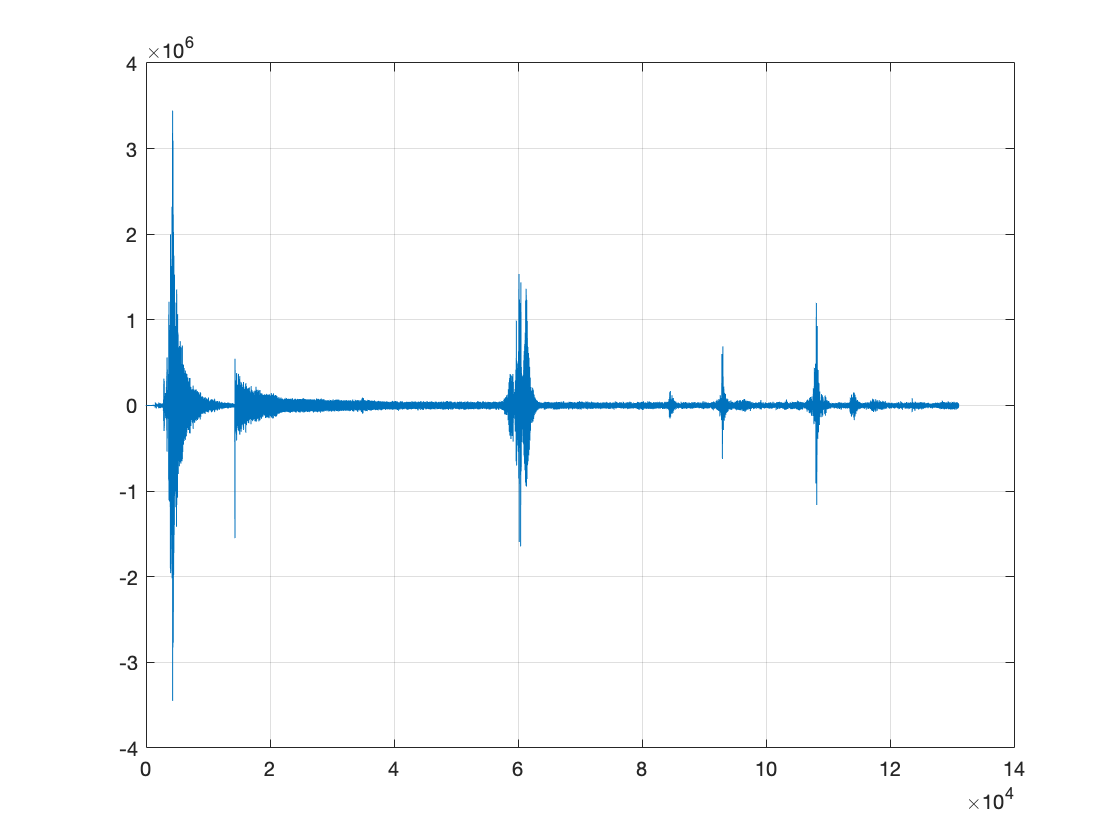

close all;
clear;

% Load golf shot data
filename = '7_Iron_Shot.txt';
AllData = fileread(filename);
[~, beg_idx] = regexp(AllData,':'); % start extracting data after ':' character is found 
AllData = AllData(beg_idx+1:end);
AllData = textscan(AllData,'%s');
GolfBallData = str2double(AllData{1}); % Data values has all the data values from the .txt file 

figure; plot(GolfBallData); grid on; 

**Parameters:**

fs = 17045; %Sampling freq
nfft = 2048; %FFT length
L = 90; %Window length
overlap = floor(0.85*L); % 50% overlap
N = 0; % User-defined. Used for adaptive threshold later.
w1 = kaiser(L,2.6);


**Signal data:**

% SIGNAL
signal = GolfBallData;
signal = signal((floor(0.15*fs)+1):floor(0.35*fs));

**Calling Spectrogram function:**

%Spectrogram 
[Spec_t,freq,Spec_mag,Spec] = spectrogram_function(signal,w1,overlap,nfft,fs);
[f_bins,nframes] = size(Spec_mag); % Number of freq bins and frames


**Adaptive threshold using modal intensity + N*(std. dev.):**

hist_length = floor(length(freq)/8); % Length hist = 1/8 of num. bins
modal_intensity = zeros(1,nframes);

for i = 1:nframes
    
    frame = Spec_mag(:,i); %Current time frame
    
    [hist,edges] = histcounts(frame,hist_length); %Get histogram counts and edges
    hist_smooth = movmean(hist,5); % Smooth with 5-pt moving avg filter
    index_modal_intensity = find(hist_smooth == max(hist_smooth)); %Index for modal intensity
    index_modal_intensity = index_modal_intensity(1); %Choose first index if max is over multiple bins
    modal_intensity(i) = (edges(index_modal_intensity)+edges(index_modal_intensity+1))/2; %Find corresponding intensity
    smooth_modal_intensity = movmean(modal_intensity,5); %Smooth noise profile
    
    threshold = smooth_modal_intensity(i) + N*std(frame); %Set threshold for current time frame
    
    for j = 1:length(freq)
       if frame(j) < threshold %If element in frame is less than threshold then set to 0
           frame(j) = 0;
       end
    end
   
    Spec_mag(:,i) = frame;
end

**Setting a target threshold:**

% FOR DISPLAY:

% for i = 1:nframes
%     frame = Spec_mag(:,i);
%     for j = 1:length(freq)
%        if frame(j) < 53
%            frame(j) = 20;
%        end
%     end
%     Spec_mag(:,i)=frame;
% end

**Peak tracking**

freq_at_peaks = zeros(1,nframes);
time_at_peaks = Spec_t;

for i = 1:nframes
    frame = Spec_mag(:,i); %Current time frame
    
    if max(frame) > 70
        
        %For curve fitting / peak tracking:
        index = frame==max(frame); % Index used to find freq. at peak
        freq_at_peaks(i) = freq(index); % frequency at peak

    else
        time_at_peaks(i) = 0;
        
    end
end
freq_at_peaks = freq_at_peaks(freq_at_peaks ~= 0);
time_at_peaks = time_at_peaks(time_at_peaks ~= 0);

**Plotting Spectrogram:**

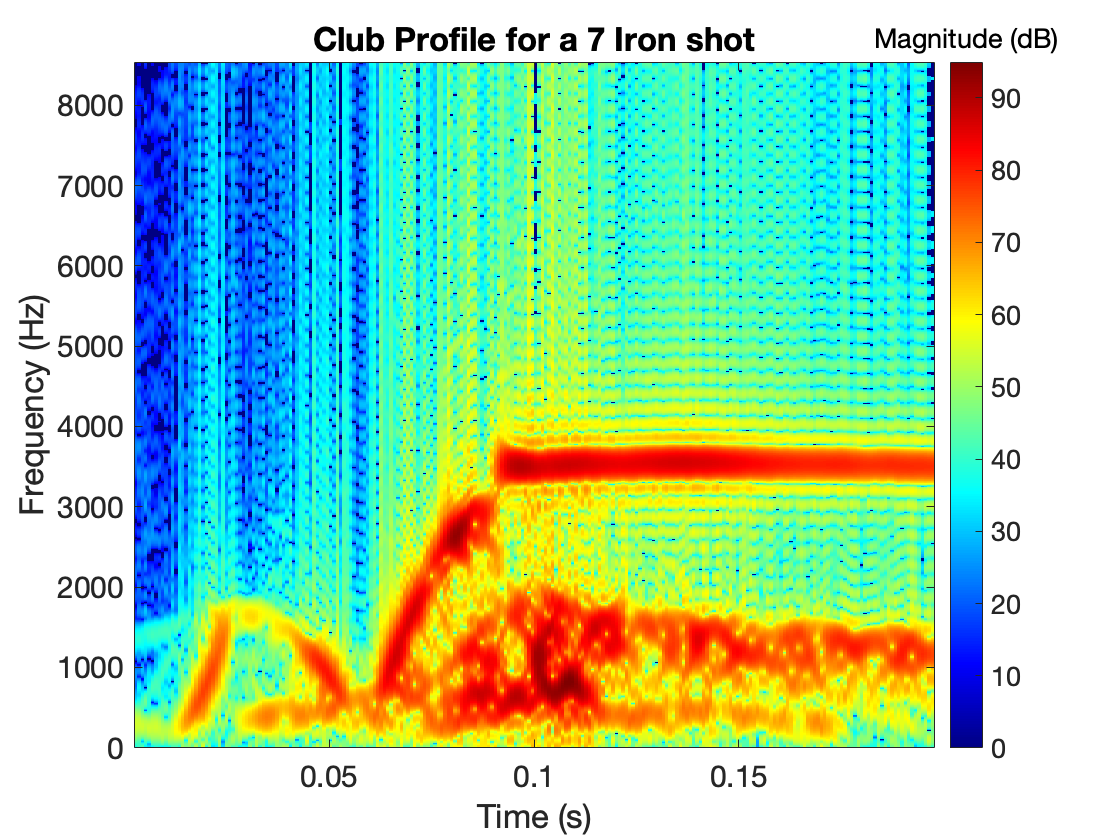

%Plotting Spectrogram

imagesc(Spec_t,freq,Spec_mag);
set(gca,'YDir','normal') % Flip y-axis such that 0 kHz is at the bottom
h = colorbar; % Create colour bar showing magnitude
colormap('jet')
set(get(h,'title'),'string','Magnitude (dB)'); % Label colourbar
title("Club Profile for a 7 Iron shot",'FontSize', 16), xlabel("Time (s)",'FontSize', 16),ylabel("Frequency (Hz)",'FontSize', 16);
set(gca,'FontSize',15);

**Plot at peaks:**

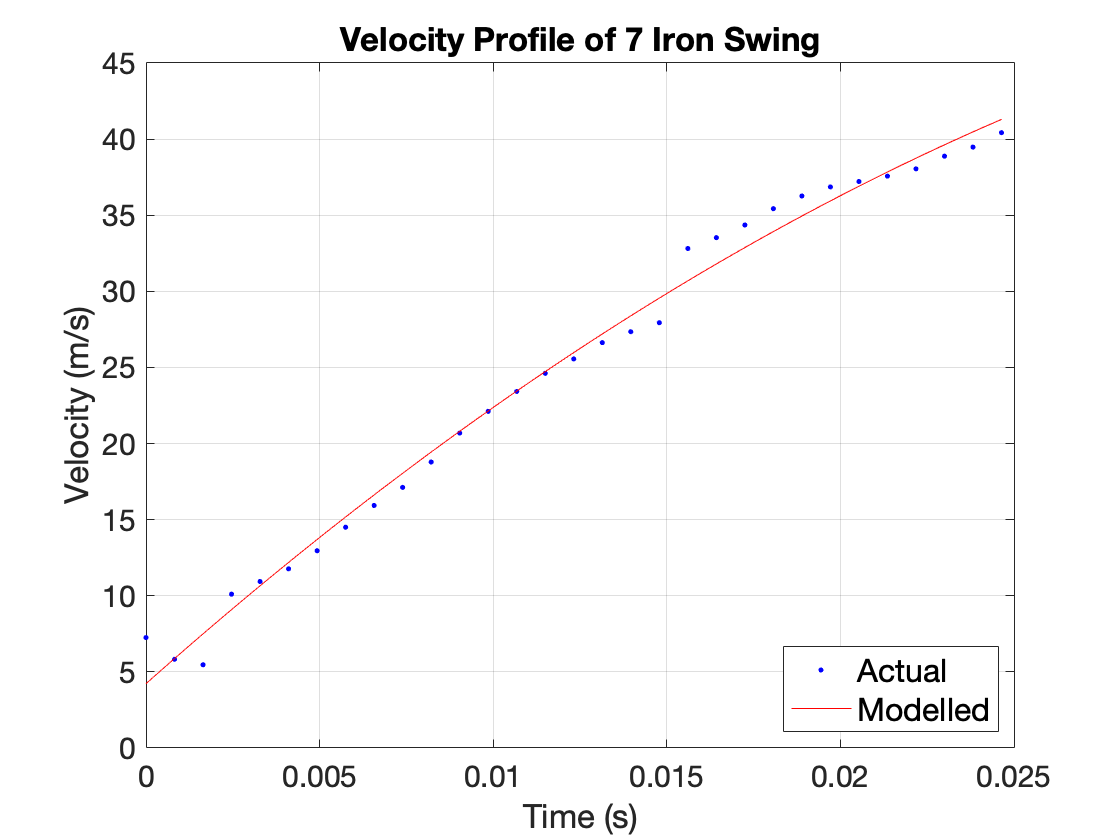

freq_at_peaks = freq_at_peaks(34:64); %downswing only
time_at_peaks = time_at_peaks(34:64);
time_at_peaks = time_at_peaks - time_at_peaks(1);

RF_freq = 10500000000; %10.5 GHz
c = 300000000; %c=3*10^8
wavelength = c/RF_freq;

vel_at_peaks = freq_at_peaks.*(wavelength/2);

[fit, gof] = club_7_iron_vel_fit(time_at_peaks, vel_at_peaks);

set(gca,'FontSize',15);

disp(fit)

     Linear model Poly2:
     fit(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =  -2.119e+04  (-3.021e+04, -1.217e+04)
       p2 =        2026  (1797, 2256)
       p3 =       4.227  (3.003, 5.451)



disp(gof)

           sse: 39.0819
       rsquare: 0.9899
           dfe: 28
    adjrsquare: 0.9891
          rmse: 1.1814



**Calculating mean error:**

%7 Iron club vel
model_at_peaks = feval(fit,time_at_peaks);
model_at_peaks = model_at_peaks.';
err = abs(model_at_peaks-vel_at_peaks);
mean_err = mean(err)

mean_err = 0.8845